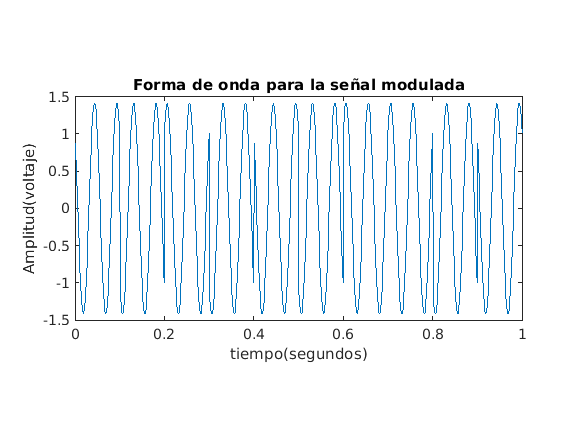

%Autores:
%Jhonatan Valencia Bolaños
%Alexander Mosquera Perdomo

%Se deben correr los archivos en este orden:
%generador - canal - destino
%Se debe contar con la lbrería Communications Toolbox
%M-QAM
M=4; %Esquema de modulación
k = log2(M); % Número de bits por simbolo
nb= 10000*k; % Número de bits a generar


y = []; %Señal a generar

%Ejecutar primero el generador y luego el destino

%***********Generador de bits equiprobables**********
    tx = randi([0,1],nb,1);

%************ Modulador M-QAM ****************
ymod = qammod(tx,M,'InputType', 'bit');



%%%%%% Gráfica real %%%%%%%
%Se extraen las componentes en magnitud y fase de la señal
%compuesta por una serie de numeros complejos que representan
%dichos valores, despues se representan en el tiempo y se suman
%teniendo en cuenta un desfase de 90 grados entre seno y coseno
RR=real(ymod);  %parte real de ymod
II=imag(ymod);  %parte imaginaria de ymod
bp=1000/nb;   %bit period
sp=bp*log2(M);  %symbol period para M-QAM
sr=1/sp;   %symbol rate
f=sr*log2(M);    %frecuencia de portadora
t=sp/100:sp/100:sp; %tiempo en base al periodo
m=[];
for i=1:1:length(RR)       %Generar señal modulada en el dominio del tiempo
    yr=RR(i)*cos(2*pi*f*t);                     %Componente real en fase
    yim=II(i)*sin(2*pi*f*t);            % Componenete imaginario cuadratura 
    y=yr+yim;
    m=[m y]; %Se concatena cada simbolo convertido en el tiempo
end
tt=sp/100:sp/100:sp*length(RR);  %eje horizontal
figure
plot(tt,m) %Gráficar la señal en el tiempo
xlim([0 1])  % limitar el eje x
pbaspect([1 0.5 1])  %dimensionar aspecto
title('Forma de onda para la señal modulada');
xlabel('tiempo(segundos)');
ylabel('Amplitud(voltaje)');
hold off

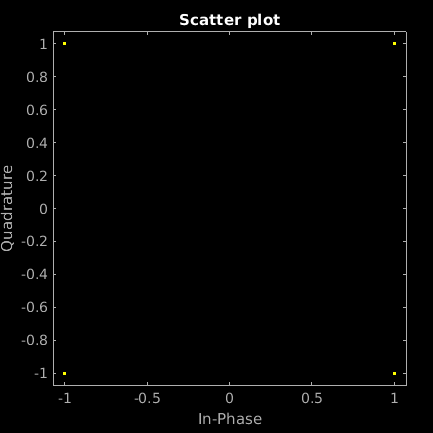

%************Gráfica de constelación**********
scatterplot(ymod)
hold off

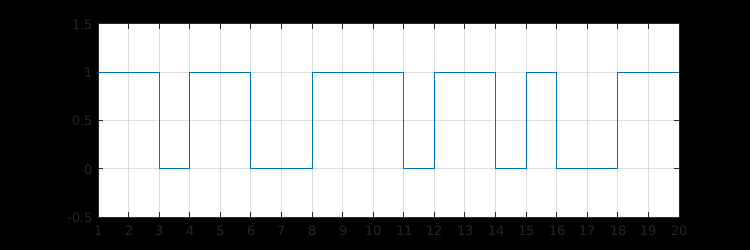


%****************Forma de Pulsos****************
ts=tx(1:20,1)'; %Se toman los primeros 20 bits generados
stairs([ts,ts(end)])%Representar los bits a manera de escalones o pulsos
%diseño visual del gráfico
hold on
ylim([-0.5 1.5])
xlim([1 length(ts)])
pbaspect([1.5 0.5 1])
xticks(0 : length(ts))
set(gcf, 'position', [10 10 750 250]);
grid on;
hold off;

save generador
